pathdata = '../../../data/sst'

pathdata = '\\10.240.13.206/public/Fluid_database/NOAA/NOAA-SST/data/'



disp('data is obtained from <a href="https://psl.noaa.gov/data/gridded/data.noaa.oisst.v2.html/">noaa.oisst.v2</a>')

data is obtained from <a href="https://psl.noaa.gov/data/gridded/data.noaa.oisst.v2.html/">noaa.oisst.v2</a>


disp('higher resolution is also available <a href="https://psl.noaa.gov/data/gridded/data.noaa.oisst.v2.highres.html/">noaa.oisst.v2 high</a>')

higher resolution is also available <a href="https://psl.noaa.gov/data/gridded/data.noaa.oisst.v2.highres.html/">noaa.oisst.v2 high</a>



dtype = "sst.wkmean.1990-present"; dmask = 'lsmask'; %! normal
% dtype = ["sst.day.mean.2021","sst.day.mean.2022"]; dmask = 'lsmask.oisst'; %! high resolution, ud is upsidedown.


ufield      = {'Uorg','Sorg','Vorg','fluc','mean'};
ufield{2,1} = [];
[u(1:size(dtype,1))]    = deal(struct(ufield{:}));
time_all    = [];

for id = 1:size(dtype,1)
    if ~isfile([pathdata,char(dtype(id)),'.mat'])
        [lat, lon, time, mask, sst]...
            = F_pre_read_NOAA_SST( [pathdata,char(dtype(id)),'.nc'], [pathdata,dmask,'.nc'] );
        save([pathdata,char(dtype(id)),'.mat'],'sst','time','mask','lat','lon','-v7.3')
    end

    load([pathdata,char(dtype(id)),'.mat'])
    n = size(find(mask),1);
    m = size(time,1);
    [u(id).Uorg, u(id).Sorg, u(id).Vorg, u(id).fluc, u(id).mean, ~] = F_pre_SVD_NOAA_SST(m, time, mask, sst);
    time_all = [time_all;time];
end
loc.mask    = mask;
loc.normal  = mask(:);

imtmp = u.mean;
ir = 10;
sptmp = [sens(ir).greedyD,sens(ir).crslcrD,sens(ir).sdpD,sens(ir).gradgreedyD]; 
[figh,p] = F_fig_SST_sensors_color_compare(imtmp,loc.mask,sptmp)

figh =   Figure (24) のプロパティ:

      Number: 24
        Name: ''
       Color: [1 1 1]
    Position: [1001 4.9950e+02 560 420]
       Units: 'pixels'

  すべてのプロパティ を表示


p = 1×4 の cell 配列
    {1×1 Line}    {1×1 Line}    {1×1 Line}    {1×1 Line}


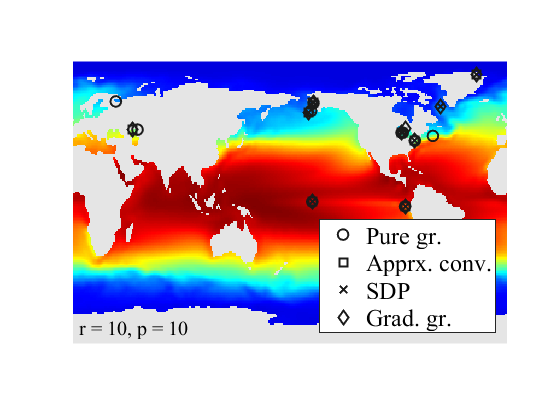

figure(figh)
hold on 
    p{1}.DisplayName = 'Pure gr.';      p{1}.MarkerEdgeColor = [0.1,0.1,0.1]; p{1}.Marker = 'o';
    p{2}.DisplayName = 'Apprx. conv.';  p{2}.MarkerEdgeColor = [0.1,0.1,0.1]; p{2}.Marker = 'square';
    p{3}.DisplayName = 'SDP';           p{3}.MarkerEdgeColor = [0.1,0.1,0.1]; p{3}.Marker = 'x';
    p{4}.DisplayName = 'Grad. gr.';     p{4}.MarkerEdgeColor = [0.1,0.1,0.1]; p{4}.Marker = 'd';

text(1,170,[' r = ',num2str(prob.r(ir)),', p = ',num2str(prob.p(ir))],'Fontsize',15,...
        'FontName','Times New Roman','Interpreter','tex');
leg = legend([p{:}],'Location','southeast');

function [f1,p] = F_fig_SST_sensors_color_compare(sensi,mask, sensors)
f1=figure();
f1.Units='pixels';
movegui('center')
%   display_sensors Template for displaying image data
%   Displays enso sensors on white w/ black continents
snapshot = NaN*zeros(numel(mask),1);
x=sensi';
snapshot(mask==1) = x;
C = reshape(real(snapshot),size(mask))';
    b = imagesc(C,'AlphaData',(~isnan(C)+0.1.*isnan(C)));
shading interp;
jetmod=jet(256);
jetmod(1,:)=0;
colormap(jetmod);
%%
%{
    c=colorbar;    %<========color bar
    if verLessThan('matlab','9.8')
    else
        f1.OuterPosition=[201 401 560 400];
        axis off
        c=colorbar();
        c.FontSize = 14;
%         c.Label.String = 'Standard deviation of Temperature [℃] ';
        c.Label.String = 'Surface Temperature [℃] ';
%         c.Label.String = 'RMSE of Temperature [K]';
        c.Label.FontName = 'TimesNewRoman';
        c.Label.FontSize = 16;
%         c.Location='northoutside'

        daspect([1.3 1 1])
    end
%}
daspect([1.3 1 1])
axis off
caxis([-5 30]);
%%
set(gca, 'FontName', 'Times','Color','white', 'FontSize', 20);


hold on;
for is = 1:size(sensors,2)
pivotA = sensors(:,is);
sensors_location = zeros(size(mask));
P = zeros(size(x));
P(pivotA)=1:length(pivotA);
sensors_location(mask==1) = P;
S = reshape(real(sensors_location)',numel(mask),1);
[~,ICA,~] = unique(S);
%! align Ilin with pivot somehow
    [I1,J1] = ind2sub(size(sensors_location'),ICA(2:end));
p{is} = plot(J1,I1,'MarkerSize', 8,'LineWidth', 1.5, 'MarkerFaceColor', 'none','LineStyle','none');
end
hold off;
end